## **Part 1**

### **1_1**

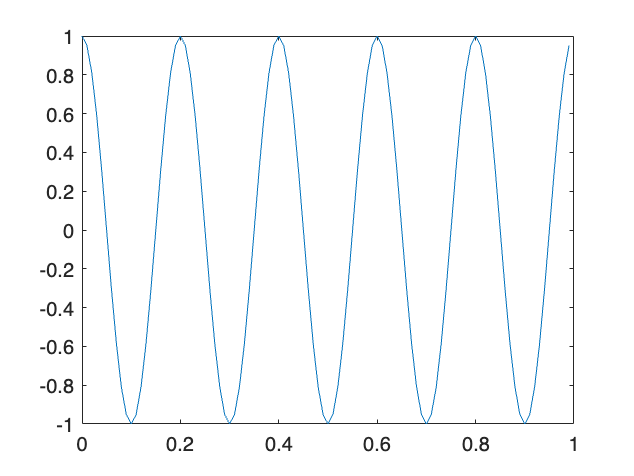

fs = 100;
ts = 1/fs;
tstart = 0;
tend = 1;
t = tstart:ts:tend-ts;
fc = 5;
x = cos (2 * pi * fc * t);

plot(t,x);

### 1_2

a = 0.5;
b = 0.3;
v = 50; % 180 km/h = 50 m/s
r = 250 * 1000; % 250 km
c = 299792458; % speed of light m/s
p = 2/c;
fd = b * v

fd = 15

td = p * r

td = 0.0017

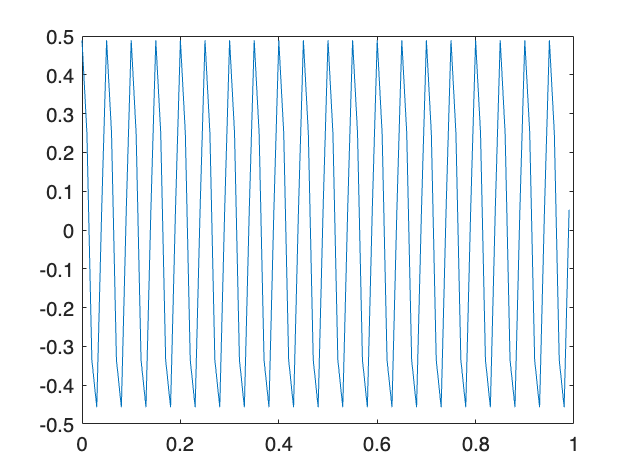



y = a * cos(2 * pi * (fc + fd) * (t - td));

plot(t, y);

### 1_3


% FFT Analysis
Y = fft(y);
n = length(y) % Number of samples

n = 100

frequencies = (0:n-1) * (fs / n) % Frequency vector

frequencies =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49



% Amplitude Spectrum
amplitude = abs(Y) / n

amplitude =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.2500    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



% Find the main frequency
[~, idx] = max(amplitude); 
main_frequency = frequencies(idx);

% Extract phase
phase_spectrum = angle(Y);
main_phase = phase_spectrum(idx);

% Display results
disp(['Main Frequency: ', num2str(main_frequency), ' Hz']);

Main Frequency: 20 Hz


disp(['Main Phase: ', num2str(main_phase), ' radians']);

Main Phase: -0.20958 radians


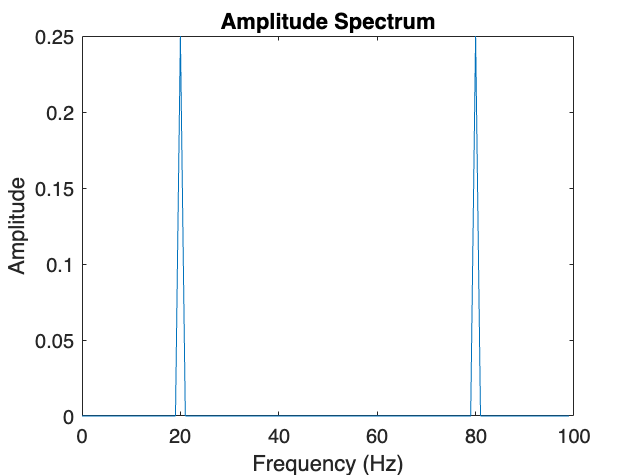


% Plot the amplitude spectrum
figure;

% We know that The FFT produces a symmetric spectrum. So we can have:
% plot(frequencies(1:floor(n/2)), amplitude(1:floor(n/2)));

% But no problem if we use this instead, which is simpler to understand
plot(frequencies, amplitude);

title('Amplitude Spectrum');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

we know that:

𝑦 ( 𝑡 ) = 𝛼 cos ( ( 2 𝜋 ( 𝑓 𝑐 + 𝑓 𝑑 ) 𝑡 − ( 2 𝜋 ( 𝑓 𝑐 + 𝑓 𝑑 ) 𝑡 𝑑 ) ) 

𝑦 ( 𝑡 ) = 𝛼 cos ( 2 𝜋 𝑓 𝑛𝑒𝑤 + 𝜑 𝑛𝑒𝑤 )

 𝑓 𝑛𝑒𝑤  =  ( 𝑓 𝑐 + 𝑓 𝑑 )

 𝜑 𝑛𝑒𝑤 = − 2 𝜋 ( 𝑓 𝑐 + 𝑓 𝑑 ) 𝑡 𝑑 = − 2 𝜋 ( 𝑓 𝑛𝑒𝑤 ) 𝑡 𝑑 

fnew = main_frequency;

fdnew = fnew - fc;
tdnew = main_phase / (-2*pi*fnew);

rnew = tdnew / p;
vnew = fdnew / b;

disp(['fd: ', num2str(fdnew), ' Hz']);

fd: 15 Hz


disp(['td: ', num2str(tdnew), ' radians']);

td: 0.0016678 radians


disp(['r: ', num2str(rnew/1000), ' km']);

r: 250 km


disp(['v: ', num2str(vnew*3.6), ' km/h']);

v: 180 km/h


### 1_4

function [main_phase, main_frequency] = calc_main_freq_and_phase(y, fs)
    % Input:
    % y  - Input signal
    % fs - Sampling frequency (Hz)

    % Perform FFT
    Y = fft(y);
    n = length(y); % Number of samples
    
    % Frequency vector (only positive frequencies)
    frequencies = (0:n/2-1) * (fs / n);
    % frequencies = (0:n-1) * (fs / n);
    
    % Amplitude spectrum (normalized)
    amplitude = abs(Y(1:n/2)) / n; % Only positive half
    % amplitude = abs(Y) / n;

    % Find the main frequency
    [~, idx] = max(amplitude); 
    main_frequency = frequencies(idx);

    % Extract phase
    phase_spectrum = angle(Y(1:n/2)); % Only positive half
    main_phase = phase_spectrum(idx);
end

function [rnew, vnew] = calc_r_and_v(pnew, fnew, fc, p, b)
    
    fdnew = fnew - fc;
    tdnew = pnew / (-2*pi*fnew);
    
    rnew = tdnew / p;
    vnew = fdnew / b;
end


noise = 0.1 * randn(size(y)); % Generate Gaussian noise with standard deviation 0.1
ynew = y + noise; % Add noise to the signal

[pnew, fnew] = calc_main_freq_and_phase(ynew,fs);
[rnew, vnew] = calc_r_and_v(pnew, fnew, fc, p, b);

% Define noise levels
noise_levels = [0.001, 0.005, 0.01, 0.05, 0.1, 0.2, 0.3, 0.5, 1, 1.5, 2, 5]; % Standard deviations of noise

% Preallocate arrays to store results
rnew_results = zeros(size(noise_levels));
vnew_results = zeros(size(noise_levels));

% Loop through different noise levels
for i = 1:length(noise_levels)
    % Generate noise and add to the signal
    noise = noise_levels(i) * randn(size(y)); % Gaussian noise
    ynew = y + noise; % Add noise to the signal

    % Calculate the main frequency and phase for the noisy signal
    [pnew, fnew] = calc_main_freq_and_phase(ynew, fs);

    % Calculate rnew and vnew using the derived frequency and phase
    [rnew, vnew] = calc_r_and_v(pnew, fnew, fc, p, b);

    % Store the results
    rnew_results(i) = rnew;
    vnew_results(i) = vnew;

    % Display results for this noise level
    disp(['Noise Level: ', num2str(noise_levels(i))]);
    disp(['New Radius (rnew): ', num2str(rnew/1000), ' km']);
    disp(['New Velocity (vnew): ', num2str(vnew*3.6), ' km/h']);
    disp('------------------------------------');
end

Noise Level: 0.001


New Radius (rnew): 249.5719 km


New Velocity (vnew): 180 km/h


------------------------------------


Noise Level: 0.005


New Radius (rnew): 246.0796 km


New Velocity (vnew): 180 km/h


------------------------------------


Noise Level: 0.01


New Radius (rnew): 247.7917 km


New Velocity (vnew): 180 km/h


------------------------------------


Noise Level: 0.05


New Radius (rnew): 240.6818 km


New Velocity (vnew): 180 km/h


------------------------------------


Noise Level: 0.1


New Radius (rnew): 251.7434 km


New Velocity (vnew): 180 km/h


------------------------------------


Noise Level: 0.2


New Radius (rnew): 220.674 km


New Velocity (vnew): 180 km/h


------------------------------------


Noise Level: 0.3


New Radius (rnew): 237.6879 km


New Velocity (vnew): 180 km/h


------------------------------------


Noise Level: 0.5


New Radius (rnew): 380.4113 km


New Velocity (vnew): 180 km/h


------------------------------------


Noise Level: 1


New Radius (rnew): 107.5812 km


New Velocity (vnew): 180 km/h


------------------------------------


Noise Level: 1.5


New Radius (rnew): 630.1962 km


New Velocity (vnew): 180 km/h


------------------------------------


Noise Level: 2


New Radius (rnew): 1364.7188 km


New Velocity (vnew): 504 km/h


------------------------------------


Noise Level: 5


New Radius (rnew): 8979.8462 km


New Velocity (vnew): -12 km/h


------------------------------------


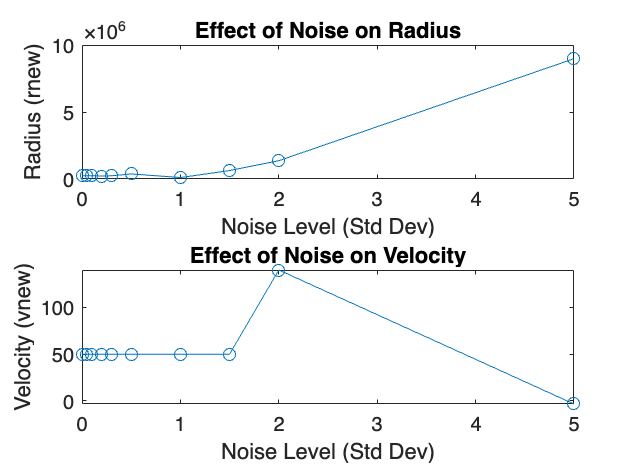


% Optionally, plot the results for analysis
figure;
subplot(2, 1, 1);
plot(noise_levels, rnew_results, '-o');
xlabel('Noise Level (Std Dev)');
ylabel('Radius (rnew)');
title('Effect of Noise on Radius');

subplot(2, 1, 2);
plot(noise_levels, vnew_results, '-o');
xlabel('Noise Level (Std Dev)');
ylabel('Velocity (vnew)');
title('Effect of Noise on Velocity');

As you can see, the "rnew" values which represent the distance are more effected by the noise rather than the "vnew" values which are our speed(velocity). distance is effected by noise around 0.2 or more, but velocity is effected by the noise around 1 or more.

### 1_5

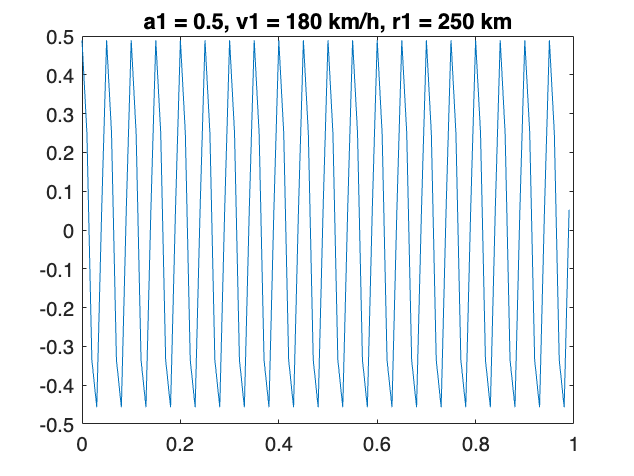

a1 = 0.5;
a2 = 0.6;

v1 = 180 / 3.6;
v2 = 216 / 3.6;

r1 = 250 * 1000;
r2 = 200 * 1000;

b = 0.3;
c = 299792458; % speed of light (m/s)
p = 2/c;

fd1 = b * v1;
td1 = p * r1;

fd2 = b * v2;
td2 = p * r2;

y1 = a1 * cos(2 * pi * (fc + fd1) * (t - td1));
y2 = a2 * cos(2 * pi * (fc + fd2) * (t - td2));

figure;
plot(t, y1);
title("a1 = 0.5, v1 = 180 km/h, r1 = 250 km");

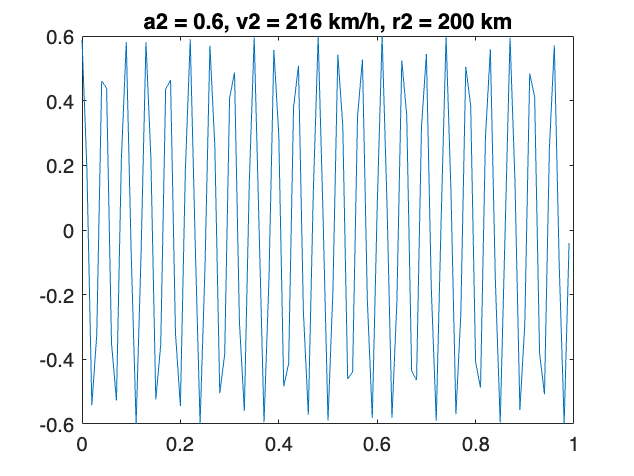


figure;
plot(t, y2);
title("a2 = 0.6, v2 = 216 km/h, r2 = 200 km");


ysum = y1 + y2;

figure;
plot(t, ysum);
title("ysum");

### 1_6

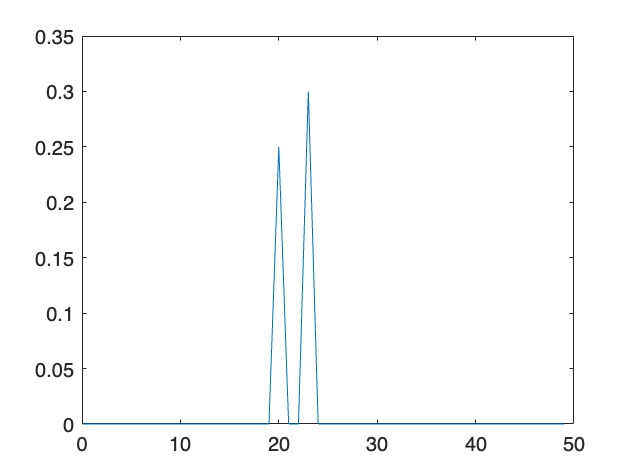

% Perform FFT
Y = fft(ysum);
n = length(ysum); % Number of samples

% Frequency vector (only positive frequencies)
frequencies = (0:n/2-1) * (fs / n);

% Amplitude spectrum (normalized)
amplitude = abs(Y(1:n/2)) / n; % Only positive half

% Find peaks and their indices
[peak_amplitudes, idx] = findpeaks(amplitude);

figure;
plot(frequencies, amplitude);


% Sort the peaks in descending order
[~, sorted_indices] = sort(peak_amplitudes, 'descend');

% Select the indices of the two largest peaks
top_two_idx = idx(sorted_indices(1:2));

% Get the corresponding frequencies and phases
top_two_frequencies = frequencies(top_two_idx);
top_two_phases = phase_spectrum(top_two_idx);

% Display the results
disp('Top two frequencies:');

Top two frequencies:


disp(top_two_frequencies);

    23    20




disp('Top two phases:');

Top two phases:


disp(top_two_phases);

   -0.9127   -0.2096



freq1 = top_two_frequencies(1);
freq2 = top_two_frequencies(2);

phase1 = top_two_phases(1);
phase2 = top_two_phases(2);

fdnew1 = freq1 - fc;
tdnew1 = phase1 / (-2*pi*freq1);

rnew1 = tdnew1 / p

rnew1 = 9.4669e+05

vnew1 = fdnew1 / b

vnew1 = 60


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
fdnew2 = freq2 - fc;
tdnew2 = phase2 / (-2*pi*freq2);

rnew2 = tdnew2 / p

rnew2 = 2.5000e+05

vnew2 = fdnew2 / b

vnew2 = 50